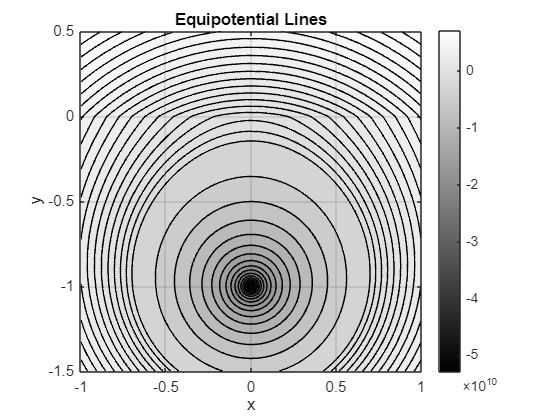

% Define constants
q = 1;
epsilon_0 = 8.854187817e-12; % Vacuum permittivity
epsilon_r = 2; % Relative permittivity
d = 1; % Distance parameter

% Define the range for x and y
x = linspace(-1, 1, 500);
y = linspace(-1.5, .5, 500);
[X, Y] = meshgrid(x, y);

% Define the potential functions
V_lower = @(x, y) (q / (2 * pi * epsilon_0 * epsilon_r)) * ...
(log(sqrt(x.^2 + (y + d).^2)) + (epsilon_r - 1) / (epsilon_r + 1) * ...
log(sqrt(x.^2 + (y - d).^2)));

V_upper = @(x, y) (q / ( pi * epsilon_0 * (epsilon_r + 1))) * ...
     log(sqrt(x.^2 + (y + d).^2));

% Calculate potentials
V = zeros(size(X));

% Apply V_lower for y < 0 and V_upper for y > 0
V(Y < 0) = V_lower(X(Y < 0), Y(Y < 0));
V(Y > 0) = V_upper(X(Y > 0), Y(Y > 0));

% Define custom contour levels to reduce density in the middle region
minV = min(V(:));
maxV = max(V(:));
levels = [linspace(minV, -100000000000, 5), linspace(-100000000000, -1000000000, 50), linspace(-1000000000, maxV, 20)];
% Plot the equipotential lines using contourf
figure;
contourf(X, Y, V, levels, 'LineWidth', 1);
colormap('gray');
colorbar;
xlabel('x');
ylabel('y');
title('Equipotential Lines');
axis equal;
grid on;

% Adjust the color axis to enhance visualization
caxis([minV maxV]);